%Parameters
   
         Ro = 2.15;
  sigma     = 0.0345;
gamma_asym  = 0.07;
 gamma_sym  = 0.07;
gamma_sev_r = 0.05;
gamma_sev_d = 0.05;
  epsilon   = 0.2;
  
 beta_asym  = Ro*(gamma_asym);
 beta_sym   = Ro*(gamma_sym);
 beta_sev   = Ro*(gamma_sev_r + gamma_sev_d);
      N     = 49650000;
      
%initial contitions      
     I0     = 5;
     S0     = N - I0;
     E0     = 0;

     R0     = 0;
     D0     = 0;

%Reading data
DATA = readtable("src\Casos_positivos_de_COVID-19_en_Colombia.csv");

dates = rmmissing(datetime(DATA.FechaDeNotificaci_n, 'InputFormat', 'yyyy-MM-dd''T''hh:mm:ss.S' ));
dates = dates(1):dates(end);
n = 1:length(dates);

[deaths, death_dates] = groupcounts(rmmissing(datetime(DATA.FechaDeMuerte, 'InputFormat', 'yyyy-MM-dd''T''hh:mm:ss.S' )));

[recovered, recovered_dates] = groupcounts(rmmissing(datetime(DATA.FechaRecuperado, 'InputFormat', 'yyyy-MM-dd''T''hh:mm:ss.S' )));

[infected_count, type] = groupcounts(DATA.Estado);

infected_asym_total = infected_count(1);
infected_sym_total = sum(infected_count(3:5)); 
infected_sev_total = infected_count(3);
deaths_total = infected_count(2);

    %parameters
  eta    = infected_asym_total / (infected_sym_total + infected_asym_total);
  nu     =  infected_sev_total / infected_sym_total;

  %initial conditions
      I_asym0 = eta*I0;
     I_sym0 = (1 - eta)*(1 - nu)*I0;
     I_sev0 = (1 - eta)*nu*I0;
     


[n, X] = ode45(@F, n, [S0; E0; I_asym0; I_sym0; I_sev0; R0; D0]);

model_asym = X(:, 3)';
model_sym = X(:, 4)';
model_sev = X(:, 5)';

model_recovered = X(:, 6)';
model_deaths    = X(:, 7)';

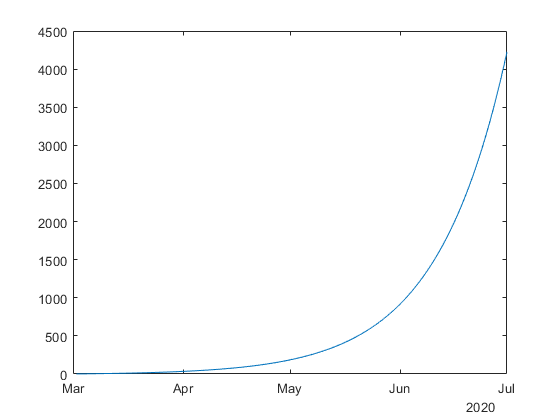

figure
plot(dates, cumulative(model_asym));

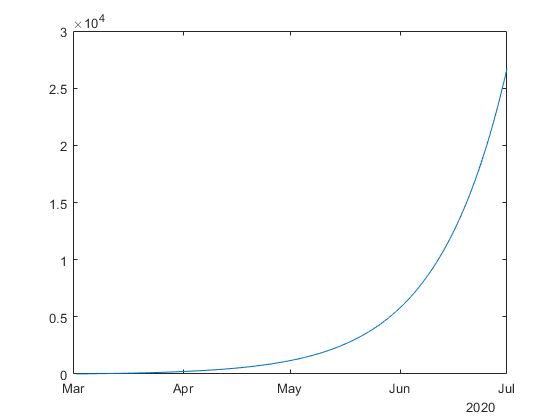


figure
plot(dates, cumulative(model_sym));

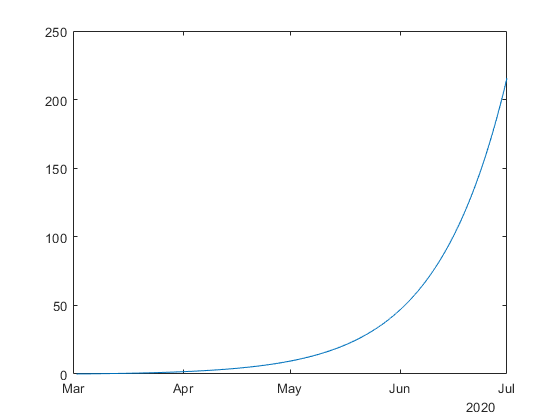


figure
plot(dates, cumulative(model_sev));

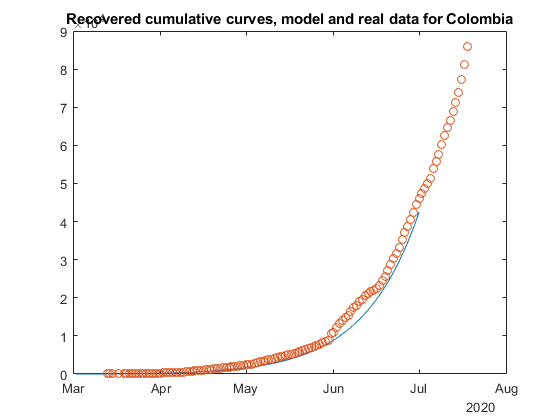

title('Sev amulative curves')

figure
plot(dates, cumulative(model_recovered))
hold on
plot(recovered_dates, cumulative(recovered), 'o')
title('Recovered cumulative curves, model and real data for Colombia')

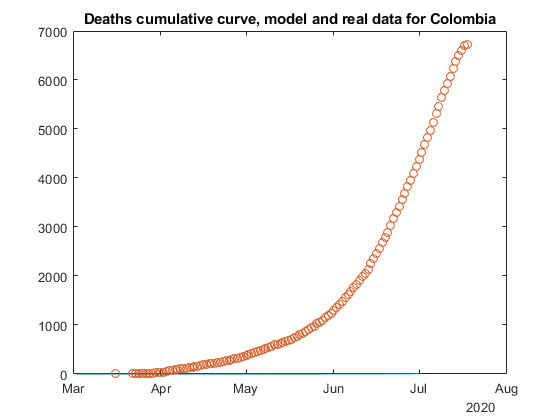


figure
plot(dates, cumulative(model_deaths));
hold on
plot(death_dates, cumulative(deaths), 'o')
title('Deaths cumulative curve, model and real data for Colombia');

function y = cumulative(x)
    y = zeros(size(x));
    y(1) = x(1);
    for k = 2 : length(x)
       y(k) = x(k) + y(k-1);
    end
end


function dX = F(t, X)

%loading parameters
 eta = evalin('base', 'eta'); nu = evalin('base', 'nu'); sigma = evalin('base', 'sigma');
 beta_asym = evalin('base', 'beta_asym'); beta_sym = evalin('base', 'beta_sym'); beta_sev = evalin('base', 'beta_sev');
 gamma_asym = evalin('base', 'gamma_asym'); gamma_sym = evalin('base', 'gamma_sym');
 gamma_sev_r = evalin('base', 'gamma_sev_r'); gamma_sev_d = evalin('base', 'gamma_sev_d'); 
 epsilon = evalin('base', 'epsilon'); N = evalin('base', 'N');    
    
    S = X(1); E = X(2); I_asym = X(3); I_sym  = X(4);
    I_sev = X(5); R = X(6); D = X(7);
    
    dX = [-(beta_asym*I_asym + beta_sym*I_sym + beta_sev*I_sev).*S/N;...
        
           (beta_asym*I_asym + beta_sym*I_sym + beta_sev*I_sev).*S/N - epsilon*E;...
           
           eta*epsilon*E - gamma_asym*I_asym;...
           
           (1 - eta)*(1 - nu)*epsilon*E - gamma_sym*I_sym;...
           
           (1 - eta)*nu*epsilon*E - ((1 - sigma)*gamma_sev_r + sigma*gamma_sev_d)*I_sev;... %TODO: here
           
           gamma_asym*I_asym + gamma_sym*I_sym + (1 - sigma)*gamma_sev_r*I_sev;...
           
           sigma*gamma_sev_d*I_sev
           
           ];
end
